In estimateModel.mlx, we learned that following structure is best:

first order no zeros plus delay.

In this file, we use tfest() to find a model of the system and then use procest() to find a model of the system plus a model of the noise filter. To test whether the noise filter is good, we perform residual analysis. Ideally, autocorrelation of residuals is low.

clear;
stepStruct = load("Simulated_stepdata.mat");
trainingStruct = load("Simulated_data1.mat");
validationStruct = load("Simulated_data2.mat");
Ts = trainingStruct.Ts;
dataStep = iddata(stepStruct.y, stepStruct.u, Ts, 'InterSample', 'zoh');
dataEst= iddata(trainingStruct.y, trainingStruct.u, Ts, 'Intersample', 'zoh');
dataVal = iddata(validationStruct.y, validationStruct.u, Ts, 'Intersample', 'zoh');
% SRIVC model from previously estimated best parameters
G_est = tf(srivc(dataEst, [1 1 23]));
present(G_est);

th =
 
  From input "u1" to output "y1":
                   0.5526
  exp(-0.23*s) * ----------
                 s + 0.8093
 
Continuous-time transfer function.



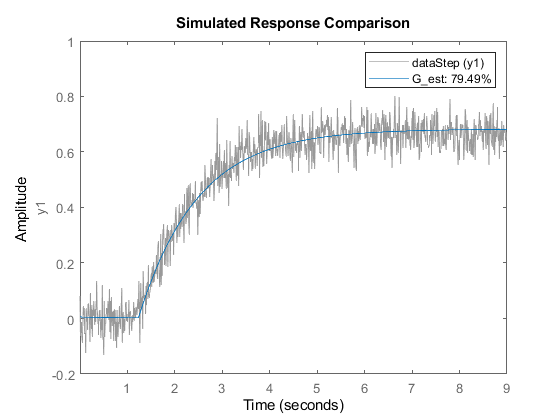

% form delay * (K / (1 + Ts))
compare(G_est, dataStep)

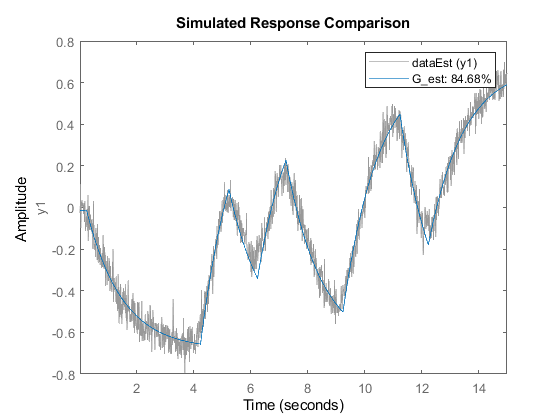

compare(G_est, dataEst)

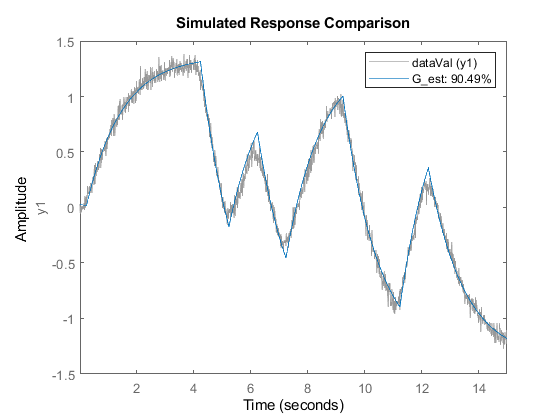

compare(G_est, dataVal)

numerator = cell2mat(G_est.Numerator);
denominator = cell2mat(G_est.Denominator);
K = numerator(end) / denominator(2)

K = 0.6827

T = 1 / denominator(2)

T = 1.2356

% provide initial values to optimization with procest() 
% initial values are obtained from our initial srivc guess
sysInit = idproc('P1D','TimeUnit','seconds');
sysInit.Structure.Kp.Value    = K;
sysInit.Structure.Kp.Minimum  = 0;
sysInit.Structure.Tp1.Value   = T;
sysInit.Structure.Tp1.Maximum = 2 * T;
sysInit.Structure.Td.Value    = 0.23;
sysInit.Structure.Td.Minimum  = 0;
sysInit.Structure.Td.Maximum  = 1;
opt = procestOptions('DisturbanceModel','ARMA1');
sysP1D = procest(dataEst,sysInit,opt)

sysP1D =
Process model with transfer function:                
             Kp                                      
  G(s) = ---------- * exp(-Td*s)                     
          1+Tp1*s                                    
                                                     
        Kp = 0.6841                                  
       Tp1 = 1.2732                                  
        Td = 0.23611                                 
                                                     
An additive ARMA disturbance model has been estimated
      y = G u + (C/D)e                               
                                                     
      C(s) = s + 15.88                               
      D(s) = s + 3.786                               
                                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 5
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          

[pvec, dpvec] = getpvec(sysP1D, 'free');
fprintf("\n\nPARAMETER VALUES WITH UNCERTAINTIES:\n")



PARAMETER VALUES WITH UNCERTAINTIES:


for i=1:length(pvec)
    fprintf('%0.4f +- %0.6f\n',pvec(i),dpvec(i));    
end

0.6841 +- 0.013862
1.2732 +- 0.045148
0.2361 +- 0.009124
15.8815 +- 2.410218
3.7858 +- 1.304474


Evaluate the P1D model

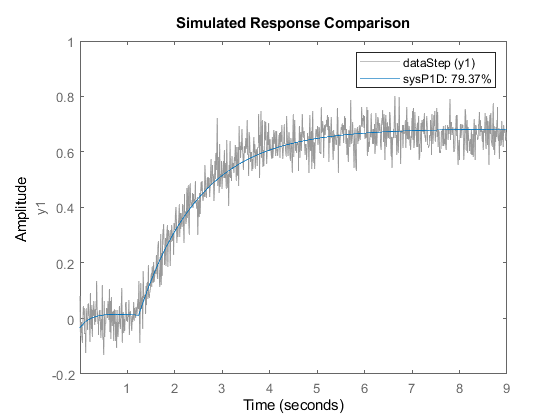

compare(sysP1D, dataStep)

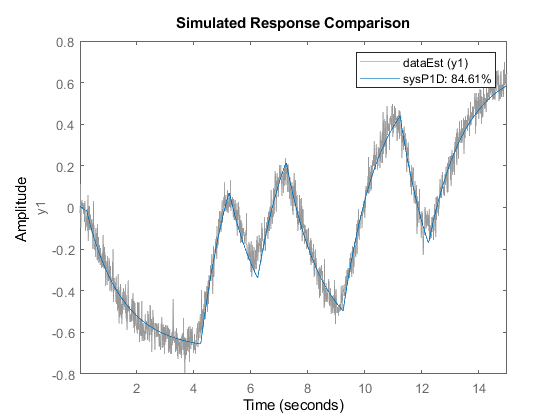

compare(sysP1D, dataEst)

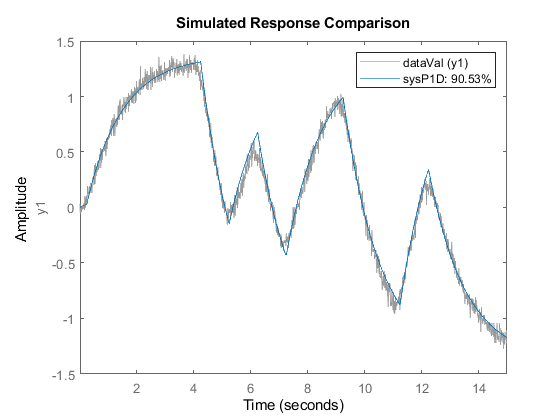

compare(sysP1D, dataVal)

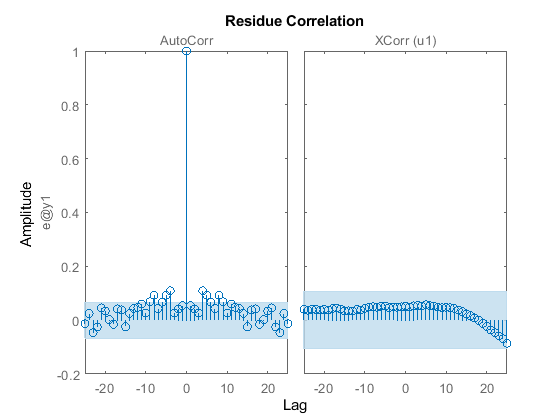

% saveFigure(gcf, 'figures/noisevalcompare')
% residual analysis
% resid(sysP1D, dataEst)
% resid(sysP1D, dataStep)
resid(sysP1D, dataVal)

% saveFigure(gcf, 'figures/noisevalresid')

% some system properties
% steady state gain: rougly K from above
steadyStateGain = dcgain(sysP1D)

steadyStateGain = 0.6841

damp(sysP1D)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -7.85e-01     1.00e+00       7.85e-01         1.27e+00    


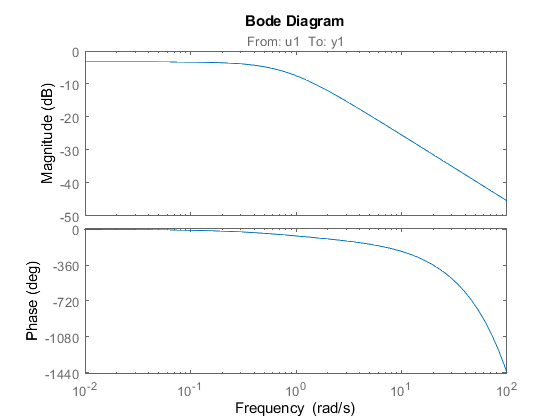

bode(sysP1D)

cutoffFrequency = 1 / sysP1D.Tp1

cutoffFrequency = 0.7854